# **Statistical tests for multivariate regression**

 clear; close all;
Name{1} = 'Daniel Gonzalez';

%% load file from .mat
%General datafile: datafile.mat
load datafile.mat % you can edit here if your datafile has a different name, but do not add path to the file (otherwise it does not work on a different computer)
whos -datafile.mat
D = datafile;

Y=D(:,1);%output (Vanilla)
x1=D(:,2);%regresor x1 (Muffin)
x2=D(:,3);%regresor x2 (Cupcake)

D = [x1, x2, Y];

# Least squares fit for the data

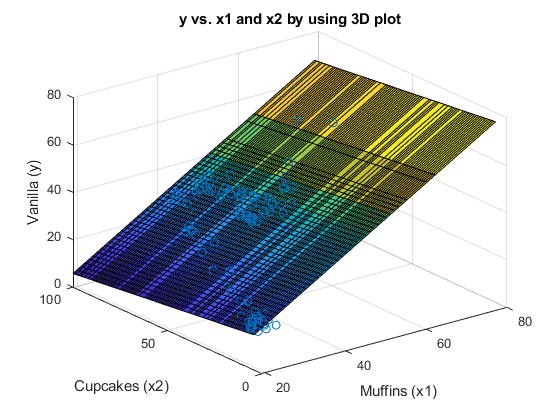

x0 = zeros(length(D), 1)+1;%regresor x0
X = [x0, x1, x2]; %Design matrix(arrays of regressors)
XTX = (X')*X;
XTY = (X')*Y;
BLS = inv(XTX) * XTY; %estimated vector of slopes


y1 = X*BLS;  %fitted values
           
[X1,X2] = meshgrid(x1, x2);
Y1 = BLS(1) + BLS(2)*X1 + BLS(3)*X2;
surf(X1, X2, Y1);

hold on            
scatter3(x1, x2, Y);
xlabel('Muffins (x1)');
ylabel('Cupcakes (x2)');
zlabel("Vanilla (y)");
title('y vs. x1 and x2 by using 3D plot');
hold off

# R^2 coefficient and F-test

%SSERR=(YT*Y) - (YT*X*BLS)
SSERR=(Y'*Y) - (Y'*X*BLS); %variance not explained by model

%SSTOT= (YT*Y) - (n*mean(Y^2)
n=length(Y);
SSTOT=(Y'*Y)- (mean(Y)*mean(Y)*n); %total squared error

%SSREG= (YT*X*BLS) - (n*mean(Y)^2)
SSREG=(Y'*X*BLS)-(mean(Y)*mean(Y)*n); %variance explained by the model

bool=(SSTOT==SSREG+SSERR);%check that sum coincides
display(["Check if SSTOT=SSREG+SSERR:",bool])

  1×2 string array

    "Check if SSTOT=SSREG+SSERR:"    "true"




%Coefficient of determination R^2
R=SSREG/SSTOT %proportion of variance explained by model high=better (until 1)

R = 0.7236


%F-test: F-obs=MSREG/MSERR
k=size(D);

ans = 3

k=k(1,2);%number of regressors

MSREG=SSREG/k; %mean squares REG(multivariate ANOVA)
MSERR= SSERR/(n-k-1); %mean squares ERR(multivariate ANOVA)

F_obs=MSREG/MSERR

F_obs = 173.6839


degrees_freedom_1=k;
degrees_freedom_2=n-k-1;
alpha=0.05;
%H0:{all slopes=0} Ha:{exists slope!=0}
acceptance_limit=finv(1-0.05,degrees_freedom_1,degrees_freedom_2)

acceptance_limit = 2.6500

if(F_obs>acceptance_limit)
    fprintf("Ho rejected")
else
    fprintf("Ho accepted")
end

Ho rejected



p_value=1-fcdf(F_obs,degrees_freedom_1,degrees_freedom_2) %the probability of having a more extreme value than this

p_value = 0

%is almost 0.

# T-test and p-values for each regressor

%Hypothesis testing on one regressor is computred with t-static and
%covariance matrix

variance_estimator=MSERR;  
COV_matrix=(inv(XTX))*variance_estimator;

var_b1=COV_matrix(2,2);
var_b2=COV_matrix(3,3);

%H0:{slope compared=0} Ha:{slope compared!=0}
t_obs_b1=BLS(2,1)/sqrt(var_b1)%t of b1= Muffin

t_obs_b1 = 16.3488

t_obs_b2=BLS(3,1)/sqrt(var_b2)%t of b2= Cupcake

t_obs_b2 = -3.8326


alpha_half=alpha/2;
degrees=n-k-1;
t_halfs=tinv(1-alpha_half,degrees);
acceptance=[-t_halfs,t_halfs]

acceptance =    -1.9720    1.9720



%compare
if(t_obs_b1>acceptance(1,2) || t_obs_b1<acceptance(1,1))
    fprintf("Ho for b1(Muffin) rejected")
else
    fprintf("Ho for b1(Muffin) accepted")
end

Ho for b1(Muffin) rejected

p_value_b1=2*(1-tcdf(t_obs_b1,degrees))

p_value_b1 = 0


if(t_obs_b2>acceptance(1,2) || t_obs_b2<acceptance(1,1))
    fprintf("Ho for b2(Cupcake) rejected")
else
    fprintf("Ho for b2(Cupcake) accepted")
end

Ho for b2(Cupcake) rejected

p_value_b2=2*tcdf(t_obs_b2,degrees)

p_value_b2 = 1.6999e-04